# 距离徙动

距离徙动的分量：


$$R(\eta)=R(\eta_c)+\frac{V_r^2\eta_c}{R(\eta_c)}(\eta-\eta_c)+\frac{1}{2}\frac{V_r^2\cos^2\theta_{r,c}}{R(\eta_c)}(\eta-\eta_c)^2$$


        
$$=R(\eta_c)-V_r\sin\theta(\eta-\eta_c)+\frac{1}{2}\frac{V_r^2\cos^2\theta_{r,c}}{R(\eta_c)}(\eta-\eta_c)^2$$


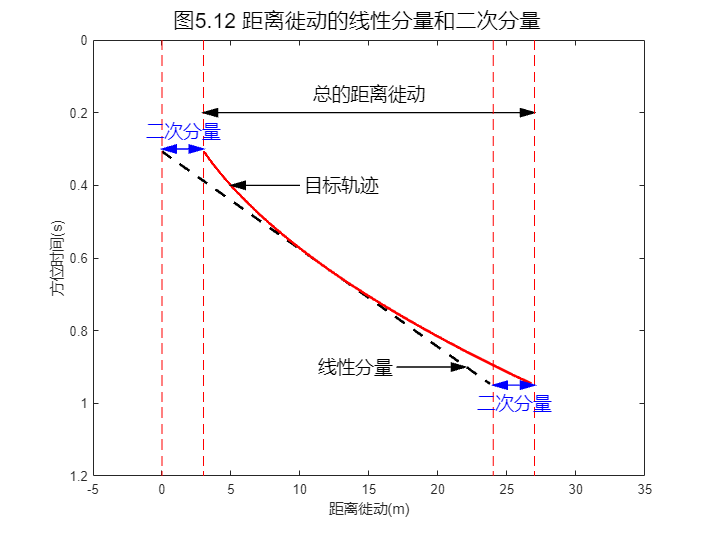

clc 
clear
close all
% 已知参数--》距离向参数
R_eta_c = 850e+3;                       % 景中心斜距
% 已知参数--》方位向参数
Vr = 7100;                              % 等效雷达速度
Ta = 0.64;                              % 目标照射时间
Ka = 2095;                              % 方位向调频率
theta_r_c = -0.3*pi/180;                % 斜视角
% 参数计算
Delta_f_dop = abs(Ka*Ta);               % 方位信号带宽
t_eta_c = -R_eta_c*sin(theta_r_c)/Vr;   % 波束中心穿越时刻
% 参数设置
alpha_a_s = 1;                          % 方位过采样率
Fa = alpha_a_s*Delta_f_dop;             % 方位采样频率PRF
Na = 2*ceil(Fa*Ta/2);                   % 方位采样点数
dt = Ta/Na;                             % 采样时间间隔
df = Fa/Na;                             % 采样频率间隔 
% 变量设置
t_eta =  (-Ta/2:dt:Ta/2-dt) + t_eta_c;  % 方位时间变量
% 信号表达
R_eta = R_eta_c -...
        Vr*sin(theta_r_c)*(t_eta-t_eta_c) +...
        (1/2)*(Vr^2*cos(theta_r_c)^2/R_eta_c)*(t_eta-t_eta_c).^2;   % 瞬时斜距展开式
%{
R_eta = sqrt(R0^2 + Vr^2*eta^2) % 瞬时斜距的双曲线形式                        
R_eta = R0 + Vr^2*eta^2/(2*R0)  % 瞬时斜距的抛物线形式                
R_eta = R_eta_c -...
        Vr^2*eta_c/R_eta_c*(eta-eta_c) +...
        (1/2)*(Vr^2*cos(theta_r_c)^2/R_eta_c)*(eta-eta_c).^2;
R_eta = R_eta_c -...
        Vr*sin(theta_r_c)*(eta-eta_c) +...
        (1/2)*(Vr^2*cos(theta_r_c)^2/R_eta_c)*(eta-eta_c).^2;
%}
RCM_1 = -Vr*sin(theta_r_c)*(t_eta-t_eta_c+Ta/2);                    % 距离徙动线性分量
RCM_2 = (1/2)*(Vr^2*cos(theta_r_c)^2/R_eta_c)*(t_eta-t_eta_c).^2;   % 距离徙动二次分量
RCM_all = RCM_1 + RCM_2;                                            % 距离徙动总量
% 绘图                                                                
H = figure();
set(H,'position',[100,100,800,600]);
plot(RCM_1,t_eta,'k--','LineWidth',2),hold on
plot(RCM_all,t_eta,'r','LineWidth',2),set(gca,'ydir','reverse')
axis([-5 35 0 1.2])
xlabel('距离徙动(m)'),ylabel('方位时间(s)')
line([0,0],[0,1.2],'Color','r','LineStyle','--')
line([3,3],[0,1.2],'Color','r','LineStyle','--')
arrow([3,0.2],[27,0.2],'Color','k','Linewidth',1);
arrow([27,0.2],[3,0.2],'Color','k','Linewidth',1);
text(15,0.15,'总的距离徙动','FontSize',14,'Color','black','HorizontalAlignment','center')
arrow([0,0.3],[3,0.3],'Color','b','Linewidth',1);
arrow([3,0.3],[0,0.3],'Color','b','Linewidth',1);
text(1.5,0.25,'二次分量','FontSize',14,'Color','blue','HorizontalAlignment','center')
line([24,24],[0,1.2],'Color','r','LineStyle','--')
line([27,27],[0,1.2],'Color','r','LineStyle','--')
arrow([24,0.95],[27,0.95],'Color','b','Linewidth',1);
arrow([27,0.95],[24,0.95],'Color','b','Linewidth',1);
text(25.5,1,'二次分量','FontSize',14,'Color','blue','HorizontalAlignment','center')
arrow([10,0.4],[5,0.4],'Color','k','Linewidth',1);
text(13,0.4,'目标轨迹','FontSize',14,'Color','black','HorizontalAlignment','center')
arrow([17,0.9],[22,0.9],'Color','k','Linewidth',1);
text(14,0.9,'线性分量','FontSize',14,'Color','black','HorizontalAlignment','center')
sgtitle('图5.12 距离徙动的线性分量和二次分量','Fontsize',16,'color','k')

**距离徙动随斜视角的变化情况**

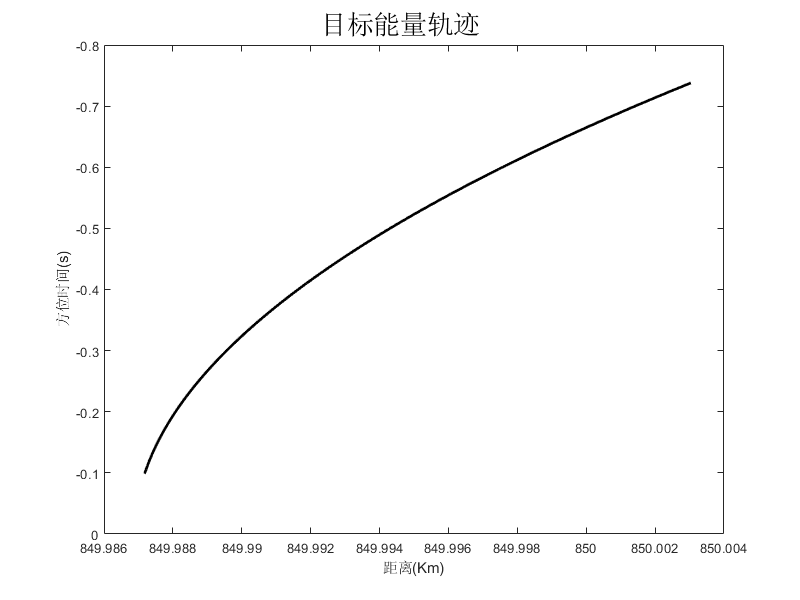

clc
clear
close all
% 已知参数--》距离向参数
R_eta_c = 850e+3;                       % 景中心斜距
% 已知参数--》方位向参数
Vr = 7100;                              % 等效雷达速度
Ta = 0.64;                              % 目标照射时间
Ka = 2095;                              % 方位向调频率
% 斜视角为正表示波束前视，斜视角为负表示波束后视
theta_r_c = 0.2*pi/180;    
% 参数计算
Delta_f_dop = abs(Ka*Ta);               % 方位信号带宽
t_eta_c = -R_eta_c*sin(theta_r_c)/Vr;   % 波束中心穿越时刻
% 参数设置
alpha_a_s = 1;                          % 方位过采样率
Fa = alpha_a_s*Delta_f_dop;             % 方位采样频率PRF
Na = 2*ceil(Fa*Ta/2);                   % 方位采样点数
dt = Ta/Na;                             % 采样时间间隔
df = Fa/Na;                             % 采样频率间隔 
% 变量设置
t_eta =  (-Ta/2:dt:Ta/2-dt) + t_eta_c;  % 方位时间变量
% 信号表达
R_eta = R_eta_c -...
        Vr*sin(theta_r_c)*(t_eta-t_eta_c+Ta/2) +...
        (1/2)*(Vr^2*cos(theta_r_c)^2/R_eta_c)*(t_eta-t_eta_c).^2;   % 瞬时斜距展开式
RCM_1 = -Vr*sin(theta_r_c)*(t_eta-t_eta_c+Ta/2);                    % 距离徙动线性分量
RCM_2 = (1/2)*(Vr^2*cos(theta_r_c)^2/R_eta_c)*(t_eta-t_eta_c).^2;   % 距离徙动二次分量
RCM_all = RCM_1 + RCM_2;                                            % 距离徙动总量
% 绘图                                                                
G = figure();                                                           
set(G,'position',[100,100,800,600]);
plot(R_eta/1000,t_eta,'k','LineWidth',2);set(gca,'ydir','reverse')
xlabel('距离(Km)'),ylabel('方位时间(s)')
sgtitle('目标能量轨迹','Fontsize',20,'color','k')

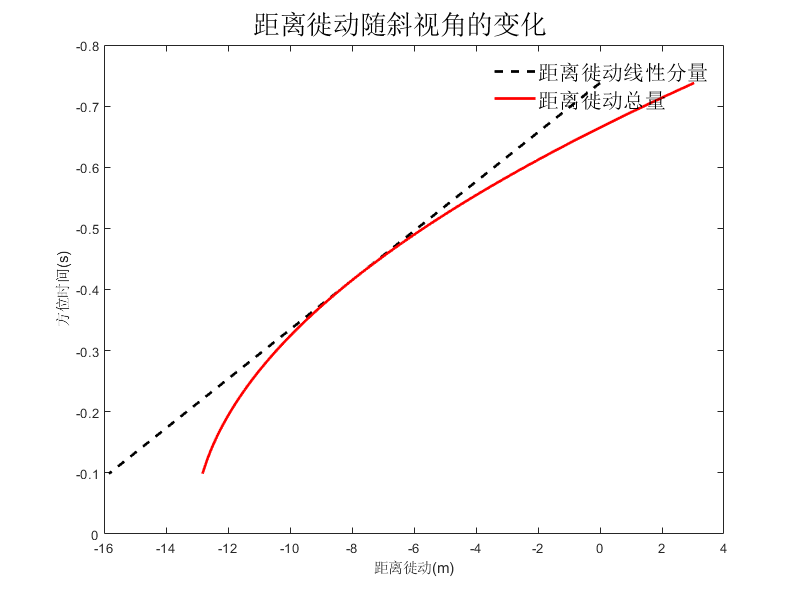

% 绘图                                                                
H = figure();                                                           
set(H,'position',[100,100,800,600]);
p1 = plot(RCM_1,t_eta,'k--','LineWidth',2);hold on
p2 = plot(RCM_all,t_eta,'r','LineWidth',2);set(gca,'ydir','reverse')
xlabel('距离徙动(m)'),ylabel('方位时间(s)')
sgtitle('距离徙动随斜视角的变化','Fontsize',20,'color','k')
% 图例
legend('boxoff');
legend([p1,p2],{'距离徙动线性分量','距离徙动总量'},'FontSize',16,'TextColor','k','Location','NorthEast','NumColumns',1);

可见，在小斜视角情况下，总的距离徙动主要由二次分量构成；在大斜视角情况下，总的距离徙动主要由线性分量构成。

**方位时域距离时域以及方位频域距离时域的目标轨迹**

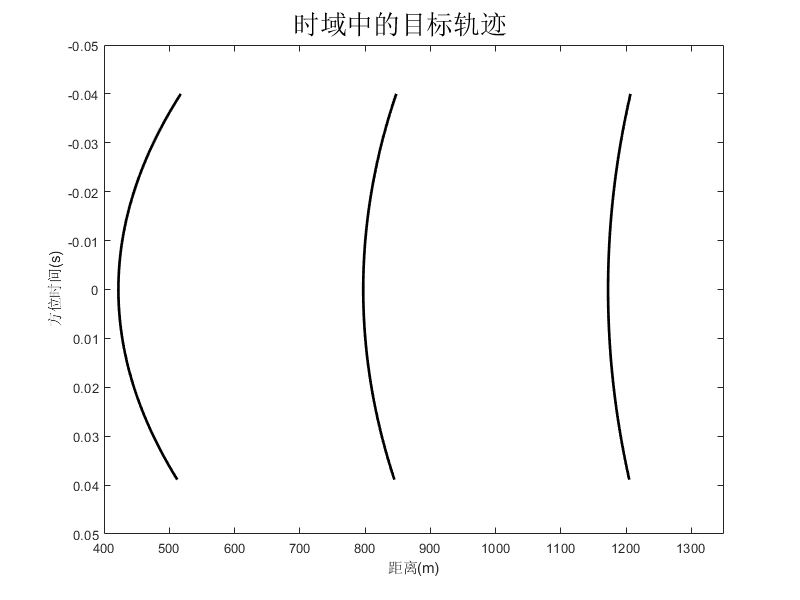

clc
clear
close all
% 已知参数--》距离向参数
R_eta_c_1 = 450;                            % 景中心斜距
R_eta_c_2 = 850;                            % 景中心斜距
R_eta_c_3 = 1250;                           % 景中心斜距
% 已知参数--》方位向参数
c  = 3e+8;                                  % 电磁传播速度
f0 = 5.3e+6;                                % 雷达工作频率
Vr = 7100;                                  % 等效雷达速度
Ta = 0.64;                                  % 目标照射时间
Ka = 2095;                                  % 方位向调频率
theta_r_c = 0*pi/180;                       % 斜视角
% 参数计算
lambda = c/f0;                              % 雷达工作波长
R0_1 = R_eta_c_1*cos(theta_r_c);            % 最短斜距
R0_2 = R_eta_c_2*cos(theta_r_c);            % 最短斜距
R0_3 = R_eta_c_3*cos(theta_r_c);            % 最短斜距
Delta_f_dop = abs(Ka*Ta);                   % 方位信号带宽
t_eta_c_1 = -R_eta_c_1*sin(theta_r_c)/Vr;   % 波束中心穿越时刻
t_eta_c_2 = -R_eta_c_2*sin(theta_r_c)/Vr;   % 波束中心穿越时刻
t_eta_c_3 = -R_eta_c_3*sin(theta_r_c)/Vr;   % 波束中心穿越时刻
% 参数设置
alpha_a_s = 1;                              % 方位过采样率
Fa = alpha_a_s*Delta_f_dop;                 % 方位采样频率PRF
Na = 2*ceil(Fa*Ta/2);                       % 方位采样点数
dt = Ta/Na;                                 % 采样时间间隔
df = Fa/Na;                                 % 采样频率间隔 
% 变量设置
t_eta =  (-Ta/16:dt:Ta/16-dt);              % 方位时间变量
f_eta =  (-Fa/16:df:Fa/16-df);              % 方位频率变量
% 信号表达
R_eta_1 = R0_1 + Vr^2*t_eta.^2/(2*R0_1);    % 目标轨迹
R_eta_2 = R0_2 + Vr^2*t_eta.^2/(2*R0_2);    % 目标轨迹
R_eta_3 = R0_3 + Vr^2*t_eta.^2/(2*R0_3);    % 目标轨迹
% 信号表达                                          
R_rd_1 = R0_1 + lambda^2*R0_1/(8*Vr^2)*f_eta.^2;    % 目标轨迹
R_rd_2 = R0_2 + lambda^2*R0_2/(8*Vr^2)*f_eta.^2;    % 目标轨迹
R_rd_3 = R0_3 + lambda^2*R0_3/(8*Vr^2)*f_eta.^2;    % 目标轨迹
% 绘图                                                                
G = figure();                                                           
set(G,'position',[100,100,800,600]);
plot(R_eta_1,t_eta,'k','LineWidth',2),hold on
plot(R_eta_2,t_eta,'k','LineWidth',2),hold on
plot(R_eta_3,t_eta,'k','LineWidth',2),set(gca,'ydir','reverse')
axis([400 1350,-0.05 +0.05])
xlabel('距离(m)'),ylabel('方位时间(s)')
sgtitle('时域中的目标轨迹','Fontsize',20,'color','k')

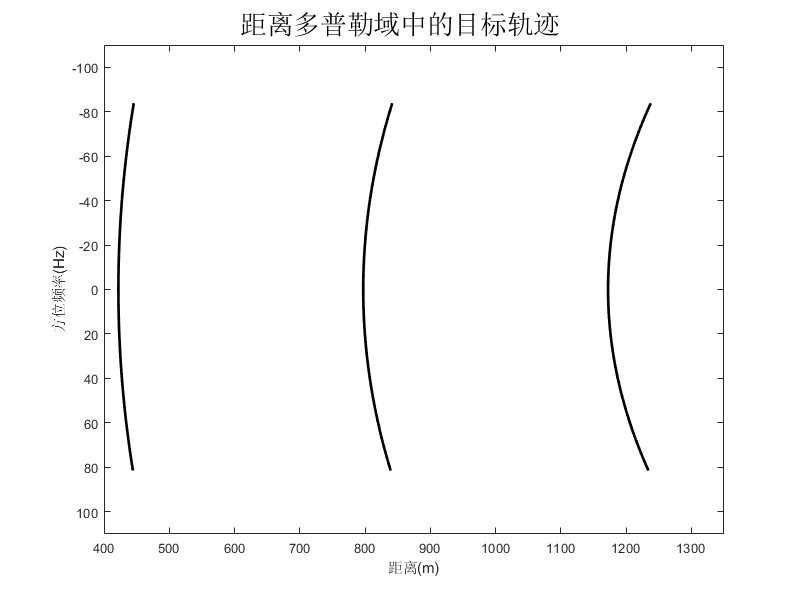

% 绘图                                                                
G = figure();                                                           
set(G,'position',[100,100,800,600]);
plot(R_rd_1,f_eta,'k','LineWidth',2),hold on
plot(R_rd_2,f_eta,'k','LineWidth',2),hold on
plot(R_rd_3,f_eta,'k','LineWidth',2),set(gca,'ydir','reverse')
axis([400 1350,-110 +110])
xlabel('距离(m)'),ylabel('方位频率(Hz)')
sgtitle('距离多普勒域中的目标轨迹','Fontsize',20,'color','k')